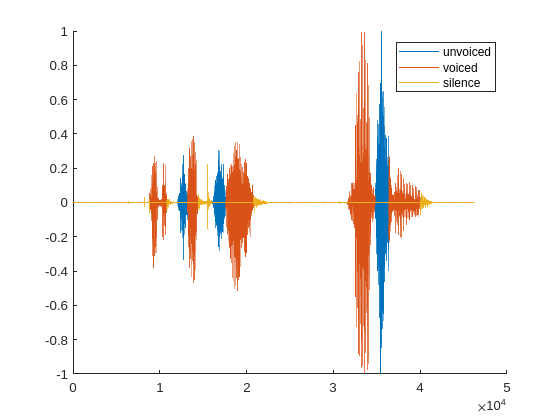

[x, fs] = audioread("percepcja.wav");
x = x / max(x);

lbls = label(x, fs);
f0 = pitchwin(x, fs, round(fs * 0.1));
f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");

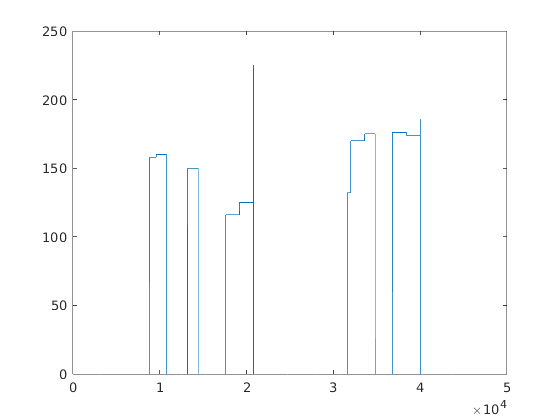


figure;
plot(f0);

Funkcja Labels:

function lbls = label(x, fs)

lbls = zeros(size(x));
voiced_threshold = 0.4;
speech_threshold = 0.06;

win = round(fs * 0.025);

% energia chwilowa
ste = conv(x.^2, ones(1,win), 'same');
ste = ste / max(ste);

% wersja z pierwiastkiem
str = sqrt(ste);

speech = zeros(size(x));
zcrs = zeros(size(x));
for i = 1 : win : length(x)-win
    if mean(str(i:i+win)) > speech_threshold
        speech(i:i+win) = 1;
    end
    zcr = zerocrossrate(x(i:i+win));
    zcrs(i:i+win) = zcr;
    if zcr > voiced_threshold
        lbls(i:i+win) = 1; % bezdzwieczne
    else
        lbls(i:i+win) = 2; % dzwieczne
    end
end
lbls = lbls .* speech;
end

Funkcja Pitchwin:

function f0 = pitchwin(x, fs, win)

f_max = 300;
lag_min = fs / f_max;

f0 = zeros(size(x));
for i=1 : win : length(x)-win
    x_tmp = x(i:i+win);
    [c, lags] = xcorr(x_tmp, "normalized");
    c = c(lags > lag_min);
    lags = lags(lags > lag_min);
    [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);
    [~, idx] = max(pks);
    if size(lags(loc(idx))) == [1 1]
        f0(i:i+win) = lags(loc(idx));
    end
end
end